# Practice Qn's

## Question 1

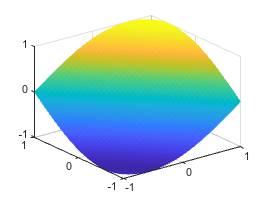

syms x y z;
[X,Y] = meshgrid(-1:0.05:1,-1:0.05:1);
Z = sin(X+Y);
surf(X,Y,Z,'EdgeColor','none');

## Question 2

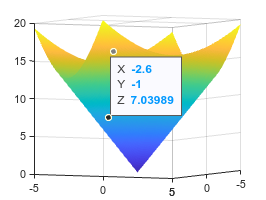

[X,Y] = meshgrid(-5:0.1:5,-5:0.1:5);
Z = sqrt(abs(6*(X.^2)+9*(Y.^2)));
surf(X,Y,Z,'EdgeColor','none');

## Question 3

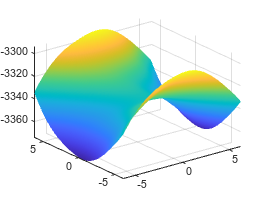

[X,Y] = meshgrid(-2*pi:0.05:2*pi,-2*pi:0.05:2*pi);
Z = sin(X+Y) - X*Y - X.^2 + Y.^2;
surf(X,Y,Z,'EdgeColor','none');

## Question 4

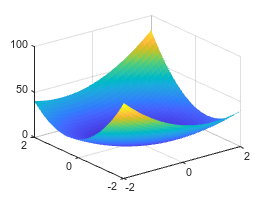

A = [3 2;
     2 5];
B = [9 4;
     4 6];
C = [-5 3;
     3 8];
D = [-1 -1;
     -1 -4];

[x1, x2] = meshgrid(-2:0.1:2, -2:0.1:2);
f = S(1,1)*x1.^2 + 2*S(1,2)*x1.*x2 + S(2,2)*x2.^2;

S = A;
surf(x1, x2, f,'EdgeColor','none');

S = B;
surf(x1, x2, f,'EdgeColor','none');

S = C;
surf(x1, x2, f,'EdgeColor','none');

S = D;
surf(x1, x2, f,'EdgeColor','none');

## Question 5

A = randn(6, 2);
S = A' * A;

% Part (a): Find eigenvalues of S to check positive definiteness
eigenvalues = eig(S);
disp('Eigenvalues of S:');

Eigenvalues of S:


disp(eigenvalues);

    3.9562
    6.4126



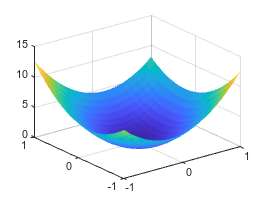


% Part (b): Plot the quadratic form f(x) = x'*S*x
[x, y] = meshgrid(-1:0.1:1, -1:0.1:1);
f = zeros(size(x));
for i = 1:size(x,1)
    for j = 1:size(x,2)
        v = [x(i,j); y(i,j)];
        f(i,j) = v' * S * v;
    end
end
figure;
surf(x, y, f,'EdgeColor','none');

## Question 6

syms x y z

% Part (a)
f = 4*x^3*exp(x*y) - y^3*z;
grad_f = gradient(f, [x, y, z])

$$grad\_f = \left(\begin{array}{c} 12\,x^{2}\,{\mathrm{e}}^{x\,y}+4\,x^{3}\,y\,{\mathrm{e}}^{x\,y}\\ 4\,x^{4}\,{\mathrm{e}}^{x\,y}-3\,y^{2}\,z\\ -y^{3} \end{array}\right)$$

hess_f = hessian(f, [x, y, z])

$$hess\_f = \begin{array}{l} \left(\begin{array}{ccc} 24\,x\,{\mathrm{e}}^{x\,y}+24\,x^{2}\,y\,{\mathrm{e}}^{x\,y}+4\,x^{3}\,y^{2}\,{\mathrm{e}}^{x\,y} & \sigma_{1} & 0\\ \sigma_{1} & 4\,x^{5}\,{\mathrm{e}}^{x\,y}-6\,y\,z & -3\,y^{2}\\ 0 & -3\,y^{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=16\,x^{3}\,{\mathrm{e}}^{x\,y}+4\,x^{4}\,y\,{\mathrm{e}}^{x\,y} \end{array}$$


% Part (b)
g = exp(x*y)*(x + y);
grad_g = gradient(g, [x, y]);
hess_g = hessian(g, [x, y]);
grad_g_at_P = subs(grad_g, [x, y], [-1, 1])

$$grad\_g\_at\_P = \left(\begin{array}{c} {\mathrm{e}}^{-1}\\ {\mathrm{e}}^{-1} \end{array}\right)$$

hess_g_at_P = subs(hess_g, [x, y], [-1, 1])

$$hess\_g\_at\_P = \left(\begin{array}{cc} 2\,{\mathrm{e}}^{-1} & 0\\ 0 & -2\,{\mathrm{e}}^{-1} \end{array}\right)$$


% Part (c)
h = (x^2 + y^2)/(x^2 - y^2);
grad_h = gradient(h, [x, y, z])

$$grad\_h = \left(\begin{array}{c} \frac{2\,x}{x^{2}-y^{2}}-\frac{2\,x\,\left(x^{2}+y^{2}\right)}{{\left(x^{2}-y^{2}\right)}^{2}}\\ \frac{2\,y}{x^{2}-y^{2}}+\frac{2\,y\,\left(x^{2}+y^{2}\right)}{{\left(x^{2}-y^{2}\right)}^{2}}\\ 0 \end{array}\right)$$

hess_h = hessian(h, [x, y, z])

$$hess\_h = \begin{array}{l} \left(\begin{array}{ccc} \frac{2}{x^{2}-y^{2}}-\frac{2\,\sigma_{4}}{\sigma_{1}}-\frac{8\,x^{2}}{\sigma_{1}}+\frac{8\,x^{2}\,\sigma_{4}}{\sigma_{3}} & \sigma_{2} & 0\\ \sigma_{2} & \frac{8\,y^{2}}{\sigma_{1}}+\frac{2\,\sigma_{4}}{\sigma_{1}}+\frac{2}{x^{2}-y^{2}}+\frac{8\,y^{2}\,\sigma_{4}}{\sigma_{3}} & 0\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(x^{2}-y^{2}\right)}^{2}\\ \sigma_{2}=-\frac{8\,x\,y\,\sigma_{4}}{\sigma_{3}}\\ \sigma_{3}={\left(x^{2}-y^{2}\right)}^{3}\\ \sigma_{4}=x^{2}+y^{2} \end{array}$$

## Question 7

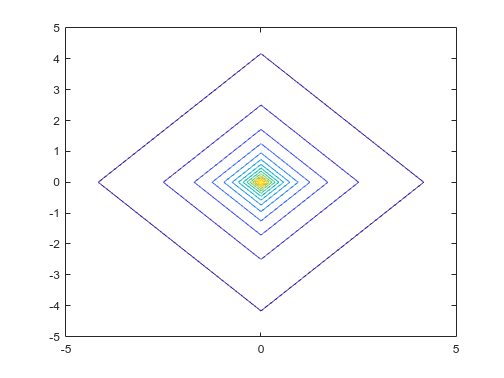

[X, Y] = meshgrid(-5:0.1:5, -5:0.1:5);
Z = 1 ./ (abs(X) + abs(Y) + 0.5);
contour(X, Y, Z, 15)

## Question 8

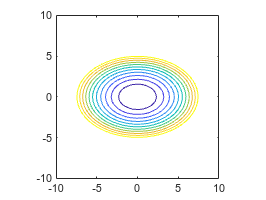

[x, y] = meshgrid(-10:0.5:10, -10:0.5:10);
f = 4*x.^2 + 9*y.^2 - 72;
v = -50:20:150;
contour(x, y, f, v, 'ShowText', 'off')
axis equal

% b
syms x y
f = 4*x^2 + 9*y^2 - 72;
grad_f = gradient(f, [x, y])

$$grad\_f = \left(\begin{array}{c} 8\,x\\ 18\,y \end{array}\right)$$

hess_f = hessian(f, [x, y])

$$hess\_f = \left(\begin{array}{cc} 8 & 0\\ 0 & 18 \end{array}\right)$$

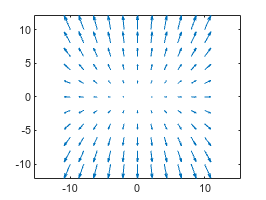

% c
[x, y] = meshgrid(-10:2:10, -10:2:10);
u = 8*x;
v = 18*y;
quiver(x, y, u, v)
axis equal

## Question 9

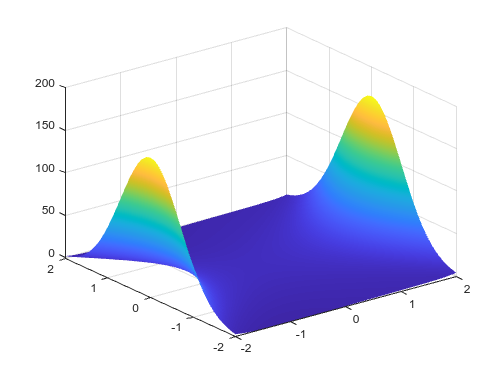

% d) Surface plot and gradient vector field on level curves

[x, y] = meshgrid(-2:0.1:2, -2:0.1:2);
f = sin(x) + cos(y) + 3*exp(x.^2 - y.^2);

figure
surf(x, y, f,'EdgeColor','none')

figure

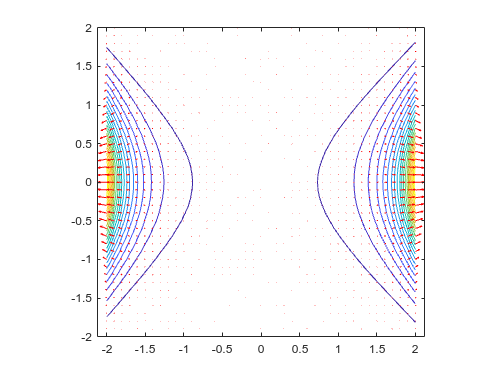

contour(x, y, f, 20, 'ShowText', 'off')
hold on

[fx, fy] = gradient(f, 0.1, 0.1);
quiver(x, y, fx, fy, 'r')
axis equal
hold off

## Question 10

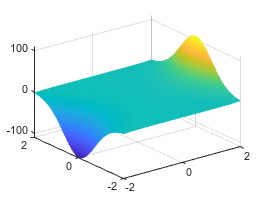

% a
[x, y] = meshgrid(-2:0.05:2, -2:0.05:2);
f = x .* exp(x.^2 - y.^2);
surf(x, y, f,'EdgeColor','none')

% b
syms x y
f = x * exp(x^2 - y^2);
grad_f = gradient(f, [x, y])

$$grad\_f = \left(\begin{array}{c} {\mathrm{e}}^{x^{2}-y^{2}}+2\,x^{2}\,{\mathrm{e}}^{x^{2}-y^{2}}\\ -2\,x\,y\,{\mathrm{e}}^{x^{2}-y^{2}} \end{array}\right)$$

hess_f = hessian(f, [x, y])

$$hess\_f = \begin{array}{l} \left(\begin{array}{cc} 4\,x^{3}\,\sigma_{1}+6\,x\,\sigma_{1} & -2\,y\,\sigma_{1}-4\,x^{2}\,y\,\sigma_{1}\\ -2\,y\,\sigma_{1}-4\,x^{2}\,y\,\sigma_{1} & 4\,x\,y^{2}\,\sigma_{1}-2\,x\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{x^{2}-y^{2}} \end{array}$$

% c
x_val = 0; y_val = 0; 
subs_hess = subs(hess_f, {x, y}, {x_val, y_val});
double_hess = double(subs_hess)

double_hess =      0     0
     0     0


% d
eigvals = eig(double_hess);

if all(eigvals > 0)
    disp('Curved upward (local min)')
elseif all(eigvals < 0)
    disp('Curved downward (local max)')
elseif any(eigvals > 0) && any(eigvals < 0)
    disp('Saddle point (curved upward and downward)')
else
    disp('Flat or undetermined')
end

Flat or undetermined
